# Project 1: Adaptive Resonance Theory

In this project, you will implement a Fuzzy ARTMAP classifier, a category of biologically inspired supervised learning models.

To keep things simple, you will use **winner-take-all** dynamics during training and testing. You will configure the model to run in **fast learning mode**, which means the network will learn based on a single pass through the data (*one-shot/single epoch learning*).

Here is the structure of the main functions:

- `artmap_train.m`: Function that implements ARTMAP training (Task 2).

- `artmap_test_wta.m`: Function that implements ARTMAP winner-take-all (WTA) testing (Task 3).

- `artmap_ensemble.m`: Main function to run model. Train and test multiple models, then vote to make predictions. Computes and reports accuracy (Task 4).

## Task 0) Getting started

To get started, make sure that you:

- Download the code templates/headers for all functions.

- Download the **circle-in-square (CIS) dataset**. The CIS100 files are a dev set to be used for debugging during development. The data are (2x100) (x,y) ordered pairs and the classes are 1x100 with 2 int values: 1 (square) and 2 (circle). The `cis_dense `files are the actual train and test sets. 

- Download the **Boston remote sensing dataset**. This is multi-class (C=8) dataset. 29,003 (N) pixels of areal images of Boston are labeled by their land type: *beach, ocean, ice, river, road, park, residential, *or *industrial. *There are 41 features derived for each pixel in an aerial image. For example, thermal readings of the ground at the location of the pixel, the pixel's intensity value, contrast, etc. You will analyze performance on this dataset after you use CIS to verify that everything is working.

- Use the test code below to test functions as you go to make yourself confident about the correctness of your code.

- After writing it, use the `plotCategoryBoxes` function to visualize/debug the train/test process. A plot of the expected category boxes after training on CSI100 with the default parameters is provided below.

- Use the excellent MATLAB debugger. At the very least, use it to check the size of variables / state of the program before crashes/errors happen.

## Task 1) Fuzzy ARTMAP Training helper methods

In Tasks 1 and 2, you will implement the ARTMAP training algorithm in `artmap_train.m`. The signature is:

`[C, w_code, w_out] = artmap_train(data_x, data_y, n_classes, verbose, varargin)`

You're welcome to proceed in any order you want: start writing `artmap_train` (see Task 2), write the helper functions first (subtasks below with test code to check your implementations), or switch back-and-forth.

### a. Preprocess input with complement coding (`complementCode.m`)

Before you train/test, you should complement code your inputs.

testCC1 = [0.1, 0.2; 0.5, 0.6; 0.7, 0.7];
testCCOut1 = complementCode(testCC1);
disp(['Shape is correct (1 means true)? ', num2str(all(size(testCCOut1) == [6, 2]))])

Shape is correct (1 means true)? 1


disp(['This should output', newline, '0.1       0.5       0.7       0.9       0.5       0.3:', newline, num2str(testCCOut1(:, 1)', 3)])

This should output
0.1       0.5       0.7       0.9       0.5       0.3:
0.1       0.5       0.7       0.9       0.5       0.3


testCC2 = [0.1, 0.2, 0.1]';
testCCOut2 = complementCode(testCC2);
disp(['Shape is correct (1 means true)? ', num2str(all(size(testCCOut2) == [6, 1]))])

Shape is correct (1 means true)? 1


disp(['This should output', newline, '0.1       0.2       0.1       0.9       0.8       0.9:', newline, num2str(testCCOut2(:, 1)', 3)])

This should output
0.1       0.2       0.1       0.9       0.8       0.9:
0.1       0.2       0.1       0.9       0.8       0.9


### b. Coding layer net input (`choiceByDifference.m`)

Given a (complement coded) data sample `curr_A`, coding units integrate the input vector via the choice-by-difference netIn function.

`                    Tj = choiceByDifference(curr_A, w_code, C, alpha, M);`

 The equation for choice-by-difference net input ton the *committed* units `j=1, ..., C` is:


$$T_j = |\vec {A}   \wedge  \vec{w}_j| + (1-\alpha)(M-|\vec{w}_j|)$$


where A is the current input vector, $\vec{w_j}$ is the wts for coding unit j, $| \vec{x} |$ is the L1 norm of x: $x_n = \left ( \sum_i | x_i | \right )$ (result $x_n$ is a SCALAR), and the wedge operator is component-wise fuzzy AND (result f is a VECTOR): $\vec{f} = \vec {p}   \wedge  \vec{q} = min(p_i, q_i)$.

rng(0);
test_input = (0.1:0.1:0.6)';
test_w_code = rand(length(test_input), 4);
C = 2;
alpha = 0.99;
M = 3;
test_Tj = choiceByDifference(test_input, test_w_code, C, alpha, M);
fprintf('test_Tj is\n%.4f %.4f and should be\n1.4196 1.7489', test_Tj);

test_Tj is
1.4196 1.7489 and should be
1.4196 1.7489

### c. Coding layer net activation: Apply threshold-linear function then rank coding unit matches high-to-low (`possibleMatchInds.m`)

The threshold-linear netAct function for the coding layer is somewhat similar to ReLU, except that (i) it filters out / excludes subthreshold values [doesn't set subthreshold values to 0] and (ii) it sorts above threshold candidate matches in high-to-low activation order. NetIn values $T_j$ match candidates must satisfy:


$$T_j > \alpha M$$


The signature of the netAct function is:

`[pm_inds, pm_sorted_inds] = possibleMatchInds(Tj, alpha, M)`

### d. Weight update (`updateWts.m`)

If the similarity between the current data sample and the weights of the next largest netAct ($T_J$) passes the vigilance test ($|\vec{A} \wedge \vec{w}_J| / M \geq \rho$) AND the data sample's class matches the one learned by coding unit $J$, then we enter a state of **resonance**, wherein we update the coding unit's weights. The update equation is:


$$\vec{w}_J(t) = \beta (\vec{A} \wedge \vec{w}_J(t-1))+(1- \beta)\vec{w}_J(t-1))$$


where A is the current input vector, $\vec{w}_J(t)$ are the wts for coding unit J at for training iteration $t$ (we are processing the $t^{th}$ sample within the epoch). The function signature is:

`w_code = updateWts(beta, curr_A, w_code, active_ind)`

where `active_ind `is another name for index `J`.

rng(0);
beta = 0.5;
test_input = (0.1:0.1:0.6)';
test_w_code = rand(length(test_input), 4);
disp(['Initial weights are', newline, num2str(testCCOut1(:, 1)')]);

Initial weights are
0.1         0.5         0.7         0.9         0.5         0.3


active_ind = 1;
test_w_code = updateWts(beta, test_input, test_w_code, active_ind);
fprintf('Updated wts are\n%.4f %.4f %.4f %.4f %.4f %.4f and should be\n0.4574 0.5529 0.1270 0.6567 0.5662 0.0975', test_w_code(:,1));

Updated wts are
0.4574 0.5529 0.1270 0.6567 0.5662 0.0975 and should be
0.4574 0.5529 0.1270 0.6567 0.5662 0.0975

### e. Match tracking (`matchTracking.m`)

If the vigilance threshold test passes for coding unit J, but there is a data/coding unit class mismatch (i.e. the network got the classification wrong during training), the vigilance level is temporarily rasied so that vigilance test wouldn't pass again (i.e. the network would not make the same mistake again if the same data sample were immediately presented). The following equation changes the vigiliance ($\rho$) after the mistake (during match tracking):


$$\rho = \frac{1}{M} | \vec{A} \wedge \vec{w}_J | + \epsilon$$


where $\epsilon$ is the match tracking constant. The function signature is

`p = matchTracking(curr_A, w_code, active_ind, M, e)`

rng(0);
test_input = (0.1:0.1:0.6)';
test_w_code = rand(length(test_input), 4);
e = 0.01;
M = 2;
active_ind = 1;
p = matchTracking(test_input, test_w_code, active_ind, M, e);
fprintf('After match tracking p is %.4f. It should be 0.7223.', p);

After match tracking p is 0.7223. It should be 0.7223.

## Task 2) Fuzzy ARTMAP training algorithm

### a. Implement training algorithm (`artmap_train.m`)

- Initialize coding layer and output layer weight matrices. The coding layer wts should initially be 0s and the output wts should initially be 1s. *Note the matrix sizes in the Return section of the function header*.

- Use the first data sample to commit the 1st cell in the coding layer (i.e. make the coding cell's weights equal to the first data sample and set the weight to the output unit coding the current sample's class to 1. The latter associates the newly committed coding cell with data sample's class). Implement this in the function: `addCommittedNode.m.` After you call `addCommittedNode`, `C` (current number of committed coding units) should be 1.

- Create a loop for training epochs. We are doing **fast learning** so number of epochs is assumed to be one, but we might as well make training general enough to support multiple epochs.

- Iterate through the rest of the training samples.

- Set vigilance back to its base level. 

- Calculate netIn via choice-by-difference.

- Calculate netAct via threshold-linear function with sorting of potential matches high-to-low.

- Start the ART search cycle for hypothesis testing: check to see if any of the potential matches (netAct values) one-by-one pass the vigilance test, in high-to-low order. **(a)** If the candidate coding unit J passes the vigilance test and the current data sample MATCHES the learned class associated with the coding unit, update the coding unit's weights. Then stop the ART search cycle and process the next data sample (go back to Step 4). **(b)** If the candidate coding unit J passes the vigilance test, BUT the current data sample MISMATCHES the learned class associated with the coding unit, do match tracking and continue the ART search cycle (continue Step 8).

- If the ART search cycle exhausts all coding unit candidates and fails to find one that passes the vigilance test, commit a new coding unit, which starts off coding the current data sample (i.e. learn a new category). Do this then go back to Step 4.

### b. Implement `plotCategoryBoxes.m` for debugging and visualization. 

- Implement the `plotCategoryBoxes `function`.`

- Add a call to `plotCategoryBoxes` in your loop that iterates thru data samples, if the parameter `show_plots` is true. 

- Train ARTMAP on the CIS100 data. Write your code in the following cell. Set `show_plot = true` so that the cell outputs your plot inline. When turning in your project, make sure that the plot is the only output (`verbose = false`).

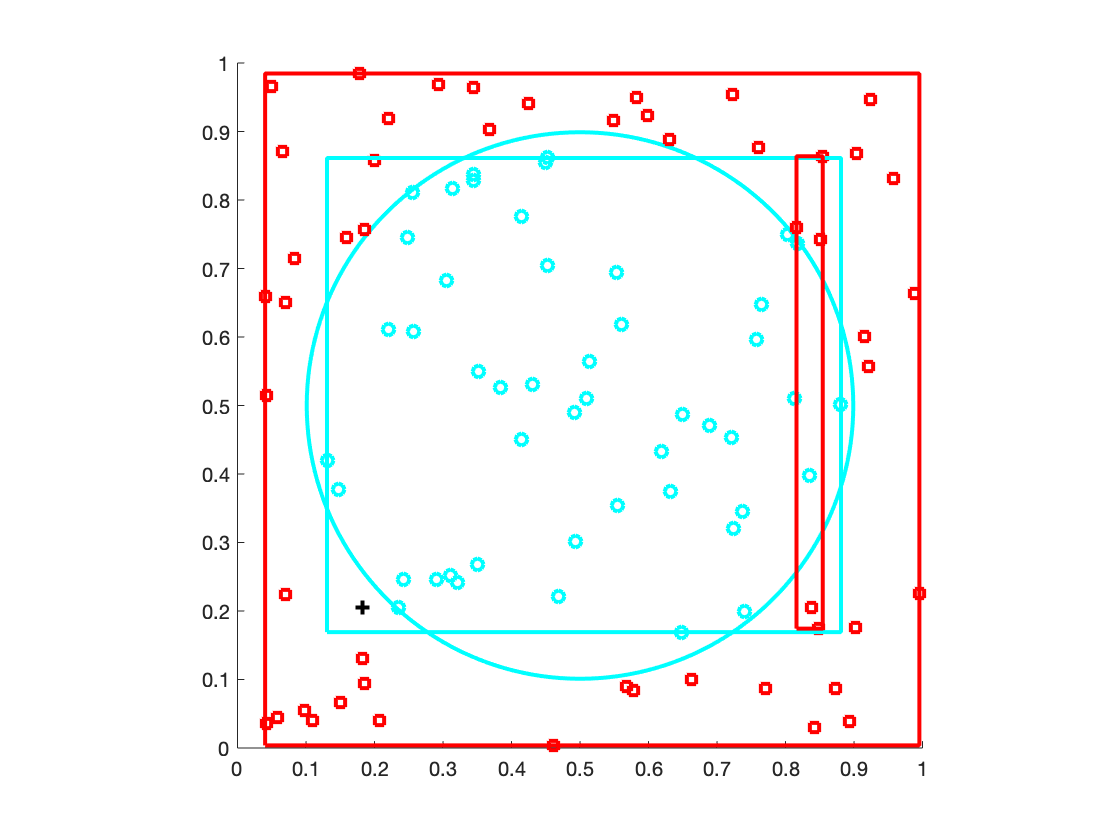

% Write CIS100 training code here
data_x = load("data/cis_x_100.mat");
data_y = load("data/cis_y_100.mat");

data_x = struct2array(data_x);
data_y = struct2array(data_y);
comp_data_x = complementCode(data_x);

[C, w_code, w_out] = artmap_train(data_x, data_y,2,1,1 );

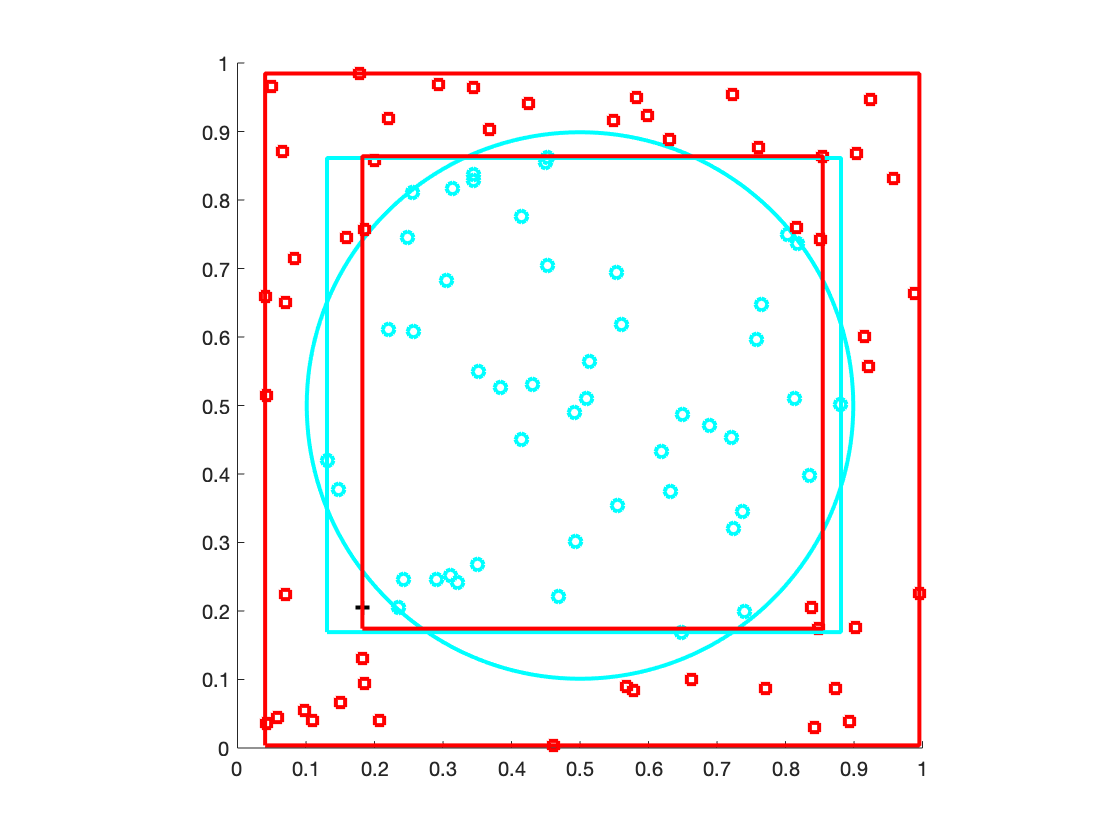

plotCategoryBoxes(comp_data_x, data_y, 100,C,w_code,w_out,"train",data_y)

% plot(data_x,data_y)

After training on all 100 samples in CIS100, this is what your plot should look like with default parameters (styling/appearance probably will probably be different):

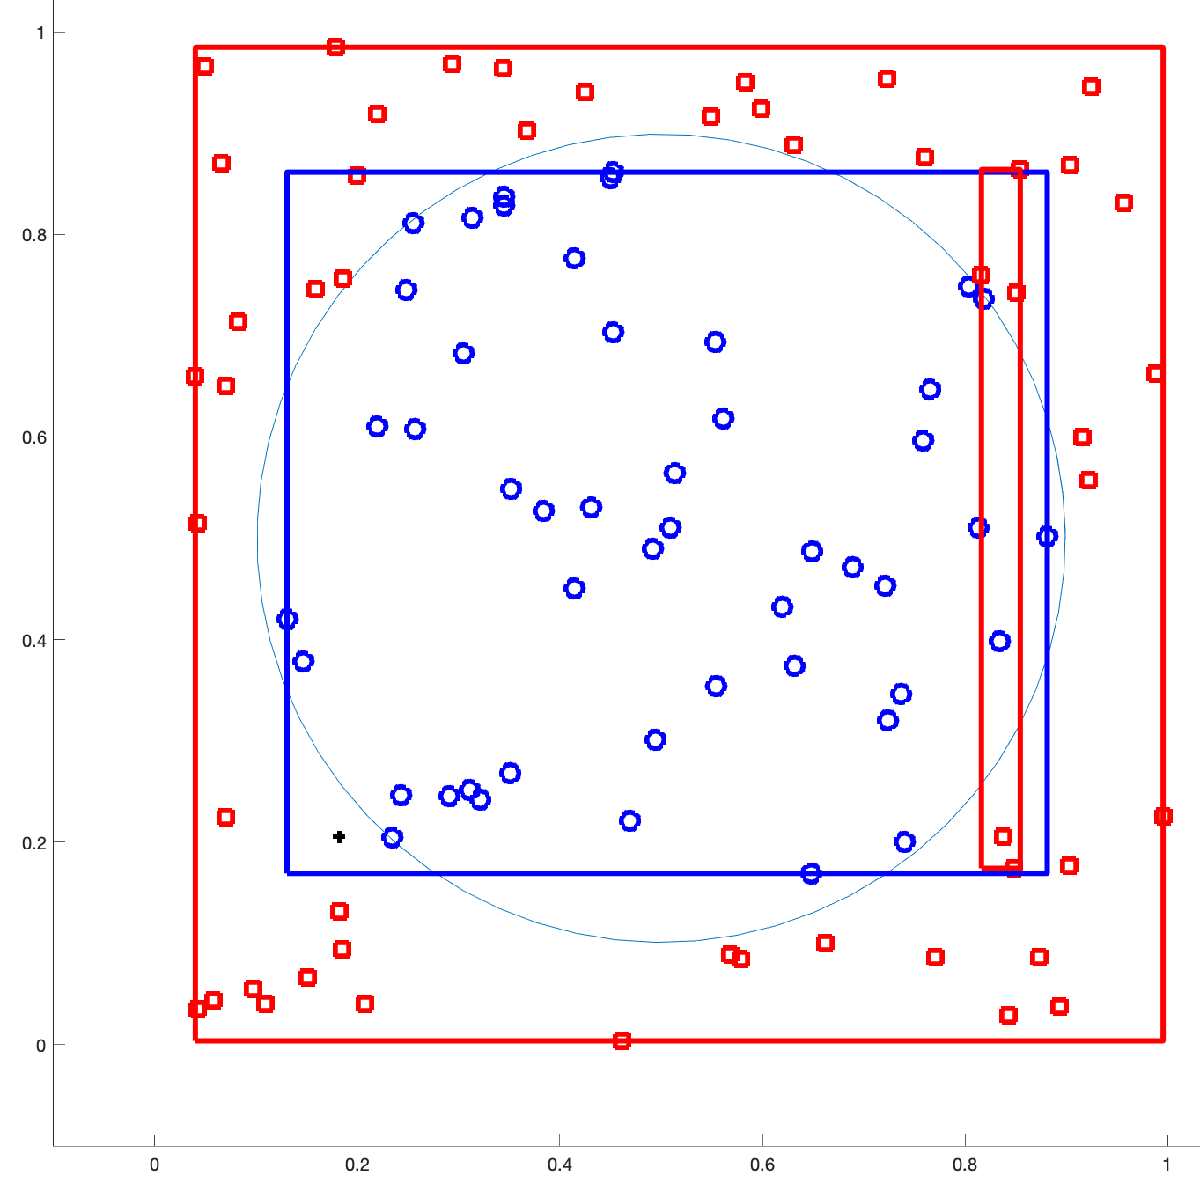

### c. Train on dense CIS dataset

Write your training code in the cell below. Write your code in the following cell. Set `show_plot = true` so that the cell outputs your plot inline. When turning in your project, make sure that the plot is the only output (`verbose = false`).

NOTE: Your code should only take a little bit of time if `verbose = true and/or show_plot = true`. If they are both `false`, the training should be almost be instant.

% Write dense training code here

dense_data_x = load("data/cis_dense_train_x.mat");
dense_data_y = load("data/cis_dense_train_y.mat");


dense_data_x = struct2array(dense_data_x);
dense_data_y = struct2array(dense_data_y);
comp_data_x = complementCode(dense_data_x);

[C, w_code, w_out] = artmap_train(dense_data_x, dense_data_y,2,1,0 )

C = 20

w_code =     0.1237    0.5906    0.4181    0.6099    0.9719    0.5618    0.8080    0.1753    0.3676    0.3135    0.7045    0.6321    0.6535    0.0798    0.0439    0.4447    0.1057    0.1300    0.7744    0.2777
    0.2758    0.7120    0.6553    0.3609    0.2094    0.7017    0.8824    0.2810    0.1758    0.4385    0.2447    0.0351    0.2953    0.4833    0.8117    0.1781    0.2116    0.5235    0.6753    0.6851
    0.8763    0.4094    0.5819    0.3901    0.0281    0.4382    0.1920    0.8247    0.6324    0.6865    0.2955    0.3679    0.3465    0.9202    0.9561    0.5553    0.8943    0.8700    0.2256    0.7223
    0.7242    0.2880    0.3447    0.6391    0.7906    0.2983    0.1176    0.7190    0.8242    0.5615    0.7553    0.9649    0.7047    0.5167    0.1883    0.8219    0.7884    0.4765    0.3247    0.3149


w_out =      1     0
     0     1
     0     1
     0     1
     1     0
     0     1
     1     0
     0     1
     0     1
     0     1


### d. Questions

- Describe in your own words what each plot is showing. Interpret the category boxes and what they mean for learning and classification.

### e. Answers

Answer 1: 

## Task 3) ARTMAP Prediction

Given the learned weights, write the test function (`artmap_test_wta.m`) that will have ARTMAP coding cells cast their votes for the output class prediction. Similar to softmax classifiers, each "vote vector" may be interpreted as a probability of classifying each test sample as belonging to class `i.` The simplest way to make a prediction is to look up the class associated with the max active coding cell (winner-take-all).

*[Extension idea: implement and experiment with a distributed coding way of making predictions — all active coding units contribute to the final vote, not just the max active. Check out the Carpenter & Amis (2007) paper on the website for the distributed code algorithm]*

### a. Implement `artmap_test_wta.m`

- There is redundancy across train/test so you might start by copying and pasting training code into `artmap_test_wta.m`. The test code is simpler so you should need to do quite a bit of deleting.

The algorithm is:

- Complement code test input. 

- Calculate the coding layer net in (Tj) for each of the test samples. 

- The predicted class of the current test sample class is the index of the coding-to-output weight vector coming from the most active coding cell that is nonzero. 

### b. Test fuzzy ARTMAP with CIS100 dataset

- In the cell below, train and test on CIS100 (*same training and test set)*.

- Shuffle the training set data indices (*keep the random seed)* once, before training.

- Set `show_plot = true `**only when evaluating the test** **set **so that the cell outputs your plot inline. When turning in your project, make sure that the plot is the only output (`verbose = false`).

% Train and test on CIS100
rng(0);


Your plot should look something like this (again, styling may different):

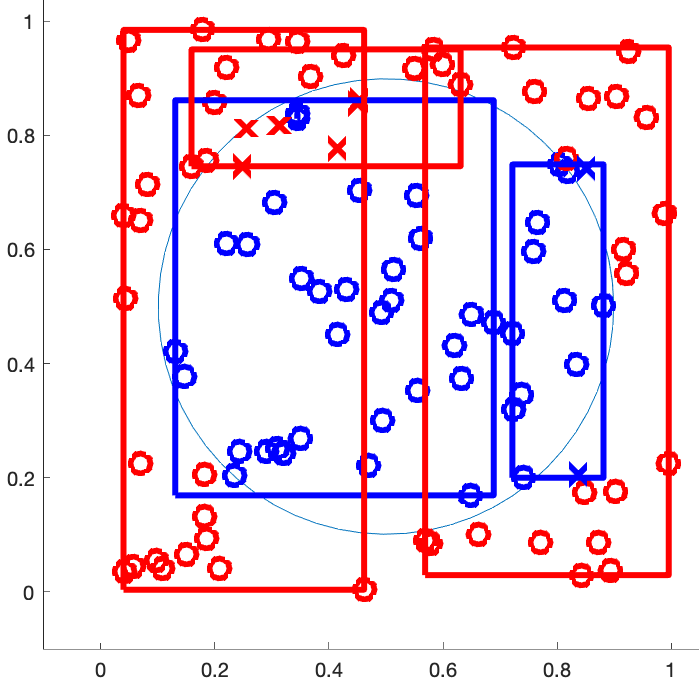

### c. Test fuzzy ARTMAP with dense CIS dataset

- In the cell below, train and test on the dense CIS dataset (different *training and test set)*.

- Shuffle the training set data indices (*keep the random seed)* once, before training.

- Set `show_plot = true `**only when evaluating the test** **set **so that the cell outputs your plot inline. Restrict the test set to the first several hundred samples, otherwise the plot will take a very long time and contain too many points to be helpful. When turning in your project, make sure that the plot is the only output (`verbose = false`).

% Test on dense CIS
rng(0);


### c. Questions

- Interpret why certain groups of classification mistakes occur using the category box plot with test samples. There should be at least a few misclassified samples, given your limited training set size.

### d. Answers

Question 1 answer:

## Task 4: Ensemble learning

Train and evaluate multiple fuzzy ARTMAP sytems to make predictions (**ensemble learning**) and investigate performance.  

### a. Implement multiple ARTMAP voters (`artmap_ensemble.m`) 

- Implement a majority vote among multiple ARTMAP systems in `artmap_ensemble.m` to classify test samples. This functon will also automate the process of training/testing on any dataset and computing the accuracy. Reuse code that you wrote in this notebook for training/testing.

- Write the code to calculate the accuracy in `accuracy.m`.

### b. Questions: Evaluate accuracy of multiple ARTMAP voters on CIS and Boston remote sensing dataset.

Write code in cells below to load the following datasets and output the accuracy that you get on each.

- What accuracy do you get with 5 voters in the CIS100 dataset?

- What accuracy do you get with 1 voters in the CIS Dense dataset?

- What accuracy do you get with 5 voters in the CIS Dense dataset?

- What accuracy do you get with 5 voters in the Boston geospatial land type dataset?

- Explain how multiple voters may improve classification performance.

% 

### c. Answers

## Extensions

- Preprocess, run, and evaluate the performance of fuzzy ARTMAP on a dataset (2D or high dimensional) of your choice. Do whatever preprocessing and analysis necessary to get as good performance as you can.

- Make a confusion matrix to analyze in more detail the Boston remote sensing dataset results.

- Implement distributed code version of prediction from the default ARTMAP paper (Section C). How does the performance compare to the WTA strategy?

- Lower beta so that the network no longer performs fast learning. You'll want to vary number of epochs as a hyperparameter. Do a thorough analysis of how this influences the classification performance and quality of the learned representations.

- Improve the visualization of the category boxes created by ARTMAP training on 2D data. Use more colors and line styles to show what's going on at more steps of the algorithm. You may want to pause the visualization at different states until the user presses a key. You could display different things when training and testing.

- Implement the Weber Law choice function to compute the `Tj` values: $T_j = \frac{|\vec{A} \wedge \vec{w}_j|}{\alpha + |\vec{w}_j|}$ and compare category learning with the choice-by-difference (CBD) function used in the main project. Note, with Weber's law, the recruitment of active coding units is slightly different: with CBD we only compute the choice function for the committed units. For Weber's law, we compute it for ALL coding units (committed or not). If the potential match score of an uncomitted node is higher than any committed nodes, allow the network to commit that node and move onto the next input sample. Do a comparative analysis of the performance, accuracy, and types of category boxes that are formed during training / selected during testing.

- Investigate what happens when you don't complement code the data. In particular, be sure to address potential differences in category formation (and number of committed coding cells).